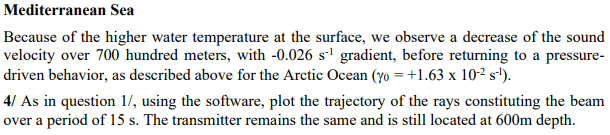

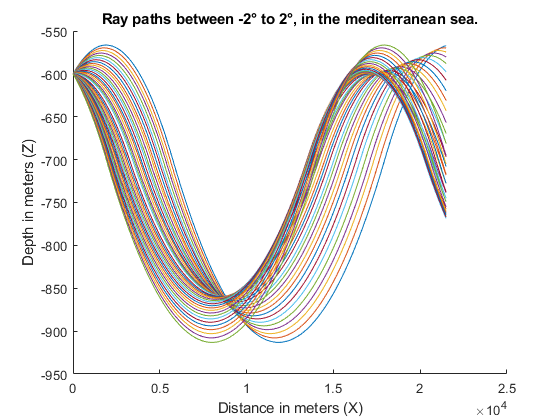

clear
clc
% Initial conditions
Co = 1450;
h = 3500 ; % Depth Seafloor
z_inv = 700;
gamma_0 = -0.026;
gamma_1 = 1.63e-2;

% Parameter difinition
zs = 600;
total_period = 15; %Total time in seconds
dt = 0.01;
t = 0:dt:total_period;
angle = -2:0.1:2;
angle = angle(angle ~= 0);
% angle = [-2 2]

n_rows = length(angle);
n_columns = length(t);

ray_matrix = zeros(n_rows, n_columns);


for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1), z_inv, Co, gamma_0, gamma_1 );
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        c(j) = velocity(z(j), z_inv, Co, gamma_0, gamma_1 );
        
        % Snail constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
    
        if (z(j) <= 0) || (z(j)>=h)
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end   
        
        ray_matrix(i,j) =  z(j);
        
    end
    
    hold on
    plot(x,-ray_matrix(i,:))
    
end

title('Ray paths between -2° to 2°, in the mediterranean sea.')
xlabel('Distance in meters (X)') 
ylabel('Depth in meters (Z)') 
hold off

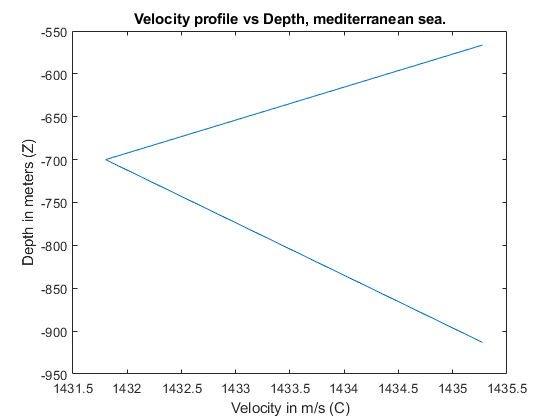

plot(c,-ray_matrix(40,:))
title('Velocity profile vs Depth, mediterranean sea.')
xlabel('Velocity in m/s (C)') 
ylabel('Depth in meters (Z)') 

dt = 0.005;
t = 0:dt:total_period;
angle = [-2];

for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1), z_inv, Co, gamma_0, gamma_1 );
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        c(j) = velocity(z(j), z_inv, Co, gamma_0, gamma_1 );
        
        % Snail constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
    
        if (z(j) <= 0) || (z(j)>=h)
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end   
        
        if x(j) >= 10000
            sprintf('For the transmitter to reach the antenna, the antenna must be located between a depth of %f and %f', z(j-1), z(j))
            sprintf('For reach a distance between in X %f and %f respectively', x(j-1), x(j))
            x = x(1:j);
            z = z(1:j);
            break
        end

    end
    

    
end

ans = 'For the transmitter to reach the antenna, the antenna must be located between a depth of 893.021742 and 893.175139'

ans = 'For reach a distance between in X 9994.437932 and 10001.611023 respectively'

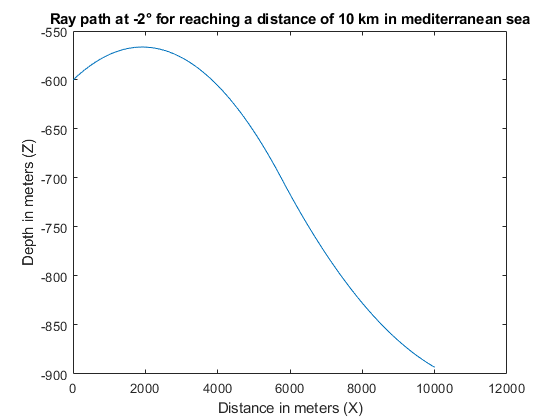

plot(x,-z)
title('Ray path at -2° for reaching a distance of 10 km in mediterranean sea')
xlabel('Distance in meters (X)') 
ylabel('Depth in meters (Z)') 

function c = velocity(z, z_inv, Co, gamma_0, gamma_1 )
    
    if z<z_inv
        c = gamma_0 * z + Co;
    else
        c_inv = gamma_0*z_inv + Co;
        b = c_inv - gamma_1*z_inv;
        c = gamma_1*z + b;
    end
    
end